### Tongue and LIp measurements at different light intensities

The data plotted in s_FluorescenceLinearity.mlx is based on measurements obtained on 3-07 and 3-08 for the 415 nm illumination

We repeated these measurements on 3-14 and 3-19 , and also included other lights (405 and 450)

Notice also that the measurements of reflected light were made on 3-17

To calculate how much light could have been reflected from the tongue, for example, we multiplied the light reflected from white surface with the mean of tongue reflectance measurements obtained from 12 participants.  This later calculation is an estimate of the maximum amount of light that could be reflected from the tongue or our participants. 

## **Initialize**

ieInit;
waves =  500:5:690;

#### Mean tongue reflectance

tongue = ieReadSpectra('tongue.mat',waves); 
% figure; plot(waves,tongue,'k'); hold on;
meanTongueReflectance = mean(tongue,2);

### Measure tongue radiance and predicted Tongue reflectance for 405 nm light

whiteSurface = ieReadSpectra('spd-2024-03-17-NoiseCheck-405nm_90mA.mat',waves); 
predictedTongueReflectance_405nm_90mA = whiteSurface .* meanTongueReflectance;
whiteSurface = ieReadSpectra('spd-2024-03-17-NoiseCheck-405nm_560mA.mat',waves); 
predictedTongueReflectance_405nm_560mA = whiteSurface .* meanTongueReflectance;
whiteSurface = ieReadSpectra('spd-2024-03-17-NoiseCheck-405nm_980mA.mat',waves); 
predictedTongueReflectance_405nm_980mA = whiteSurface .* meanTongueReflectance;

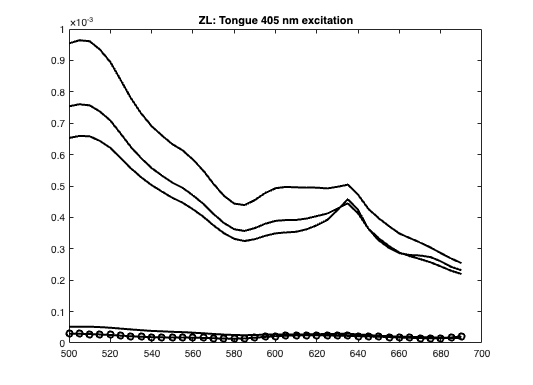

% Zhenyi
ieNewGraphWin; 
Z_tongue = ieReadSpectra('spd-2024-03-14-Z-405nm_tongue_90mA.mat',waves);       plot(waves,Z_tongue,'k','LineWidth',2); hold on;
Z_tongue = ieReadSpectra('spd-2024-03-14-Z-405nm_tongue_560mA.mat',waves);      plot(waves,Z_tongue,'k','LineWidth',2); hold on;
Z_tongue = ieReadSpectra('spd-2024-03-14-Z-405nm_tongue_980mA-1.mat',waves);    plot(waves,Z_tongue,'k','LineWidth',2); hold on;
Z_tongue = ieReadSpectra('spd-2024-03-14-Z-405nm_tongue_980mA.mat',waves);      plot(waves,Z_tongue,'k','LineWidth',2); hold on;
plot(waves,predictedTongueReflectance_405nm_980mA ,'k-o','LineWidth',2);
title('ZL: Tongue 405 nm excitation');

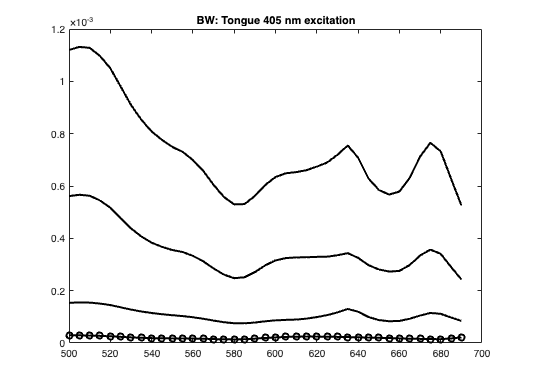

% Brian
ieNewGraphWin; 
B_tongue = ieReadSpectra('spd-2024-03-19-B_405nm_tongue_90mA.mat',waves);   plot(waves,B_tongue,'k','LineWidth',2); hold on;
B_tongue = ieReadSpectra('spd-2024-03-19-B_405nm_tongue_560mA.mat',waves);   plot(waves,B_tongue,'k','LineWidth',2); hold on;
B_tongue = ieReadSpectra('spd-2024-03-19-B_405nm_tongue_980mA.mat',waves);   plot(waves,B_tongue,'k','LineWidth',2); hold on;
plot(waves,predictedTongueReflectance_405nm_980mA ,'k-o','LineWidth',2);
title('BW: Tongue 405 nm excitation');

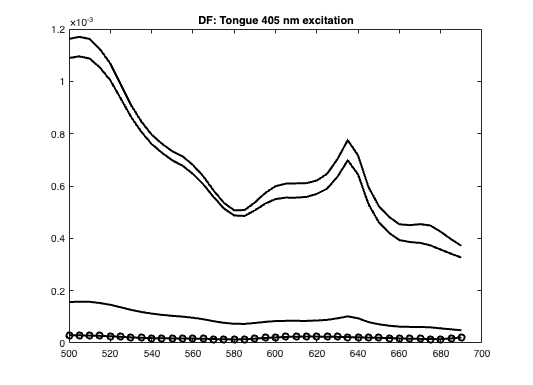

% Doug
ieNewGraphWin; 
D_tongue = ieReadSpectra('spd-2024-03-19-D_4050nm_tongue_90mA.mat',waves);   plot(waves,D_tongue,'k','LineWidth',2); hold on;
D_tongue = ieReadSpectra('spd-2024-03-19-D_405nm_tongue_90mA.mat',waves);   plot(waves,D_tongue,'k','LineWidth',2); hold on;
D_tongue = ieReadSpectra('spd-2024-03-19-D_4050nm_tongue_980mA.mat',waves);   plot(waves,D_tongue,'k','LineWidth',2); hold on;
D_tongue = ieReadSpectra('spd-2024-03-19-D_405nm_tongue_980mA.mat',waves);   plot(waves,D_tongue,'k','LineWidth',2); hold on;
D_tongue = ieReadSpectra('spd-2024-03-19-D_405nm_tongue_560mA.mat',waves);   plot(waves,D_tongue,'k','LineWidth',2); hold on;
plot(waves,predictedTongueReflectance_405nm_980mA ,'k-o','LineWidth',2);
title('DF: Tongue 405 nm excitation');

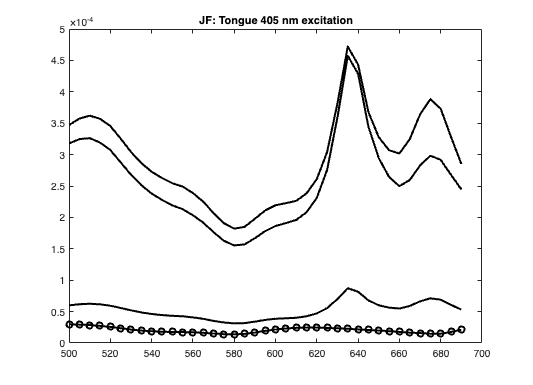

% Joyce
ieNewGraphWin; 
J_tongue = ieReadSpectra('spd-2024-03-12-11-405nm-J-tongue-90mA.mat',waves);   plot(waves,J_tongue,'k','LineWidth',2); hold on;
J_tongue = ieReadSpectra('spd-2024-03-12-11-405nm-J-tongue-560mA.mat',waves);   plot(waves,J_tongue,'k','LineWidth',2); hold on;
J_tongue = ieReadSpectra('spd-2024-03-12-11-405nm-J-tongue-980mA.mat',waves);   plot(waves,J_tongue,'k','LineWidth',2); hold on;
plot(waves,predictedTongueReflectance_405nm_980mA ,'k-o','LineWidth',2);
title('JF: Tongue 405 nm excitation');

### Measure tongue radiance and predicted Tongue reflectance for 415 nm light


whiteSurface = ieReadSpectra('spd-2024-03-17-NoiseCheck-415nm_80mA.mat',waves); 
predictedTongueReflectance_415nm_80mA = whiteSurface .* meanTongueReflectance;
whiteSurface = ieReadSpectra('spd-2024-03-17-NoiseCheck-415nm_460mA.mat',waves); 
predictedTongueReflectance_415nm_460mA = whiteSurface .* meanTongueReflectance;
whiteSurface = ieReadSpectra('spd-2024-03-17-NoiseCheck-415nm_910mA.mat',waves); 
predictedTongueReflectance_415nm_910mA = whiteSurface .* meanTongueReflectance;

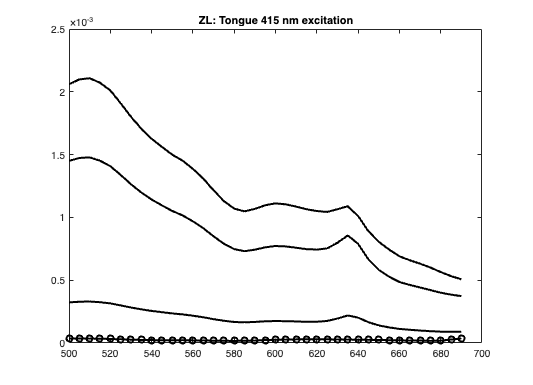

ieNewGraphWin;
Z_tongue = ieReadSpectra('spd-2024-03-14-Z-415nm_Tongue_80mA.mat',waves);   plot(waves,Z_tongue,'k','LineWidth',2); hold on;
Z_tongue = ieReadSpectra('spd-2024-03-14-Z-415nm_Tongue_460mA.mat',waves);   plot(waves,Z_tongue,'k','LineWidth',2); hold on;
Z_tongue = ieReadSpectra('spd-2024-03-14-Z-415nm_Tongue_910mA.mat',waves);   plot(waves,Z_tongue,'k','LineWidth',2); hold on;
plot(waves,predictedTongueReflectance_415nm_910mA ,'k-o','LineWidth',2);
title('ZL: Tongue 415 nm excitation');

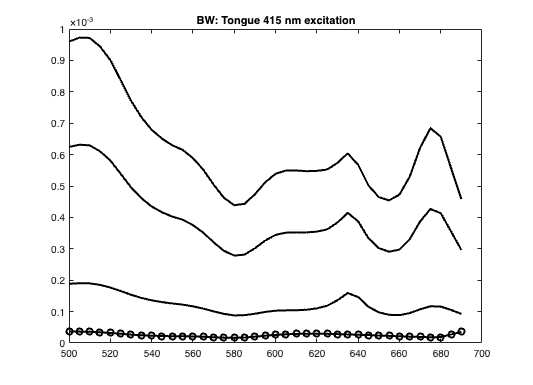

ieNewGraphWin; 
B_tongue = ieReadSpectra('spd-2024-03-19-B_415nm_tongue_80mA.mat',waves);   plot(waves,B_tongue,'k','LineWidth',2); hold on;
B_tongue = ieReadSpectra('spd-2024-03-19-B_415nm_tongue_460mA.mat',waves);   plot(waves,B_tongue,'k','LineWidth',2); hold on;
B_tongue = ieReadSpectra('spd-2024-03-19-B_415nm_tongue_910mA.mat',waves);   plot(waves,B_tongue,'k','LineWidth',2); hold on;
plot(waves,predictedTongueReflectance_415nm_910mA ,'k-o','LineWidth',2);
title('BW: Tongue 415 nm excitation');

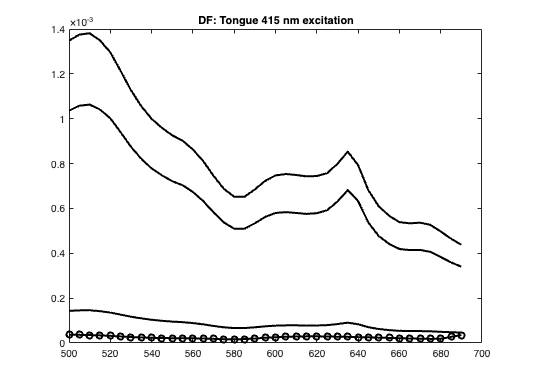

ieNewGraphWin; 
D_tongue = ieReadSpectra('spd-2024-03-19-D_415nm_tongue_80mA.mat',waves);   plot(waves,D_tongue,'k','LineWidth',2); hold on;
D_tongue = ieReadSpectra('spd-2024-03-19-D_4150nm_tongue_80mA.mat',waves);   plot(waves,D_tongue,'k','LineWidth',2); hold on;
D_tongue = ieReadSpectra('spd-2024-03-19-D_415nm_tongue_460mA.mat',waves);   plot(waves,D_tongue,'k','LineWidth',2); hold on;
D_tongue = ieReadSpectra('spd-2024-03-19-D_415nm_tongue_910mA.mat',waves);   plot(waves,D_tongue,'k','LineWidth',2); hold on;
plot(waves,predictedTongueReflectance_415nm_910mA ,'k-o','LineWidth',2);
title('DF: Tongue 415 nm excitation');

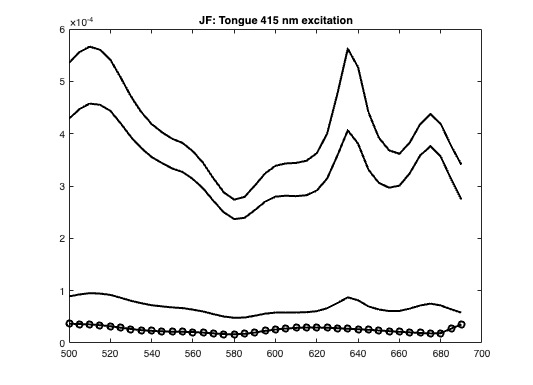

ieNewGraphWin; 
J_tongue = ieReadSpectra('spd-2024-03-12-11-415nm-J-tongue-80mA.mat',waves);   plot(waves,J_tongue,'k','LineWidth',2); hold on;
J_tongue = ieReadSpectra('spd-2024-03-12-11-415nm-J-tongue-460mA.mat',waves);   plot(waves,J_tongue,'k','LineWidth',2); hold on;
J_tongue = ieReadSpectra('spd-2024-03-12-11-415nm-J-tongue-910mA.mat',waves);   plot(waves,J_tongue,'k','LineWidth',2); hold on;
plot(waves,predictedTongueReflectance_415nm_910mA ,'k-o','LineWidth',2);
title('JF: Tongue 415 nm excitation');

### Measure tongue radiance and predicted Tongue reflectance for 450 nm light

whiteSurface = ieReadSpectra('spd-2024-03-17-NoiseCheck-450nm_90mA.mat',waves); 
predictedTongueReflectance_450nm_90mA = whiteSurface .* meanTongueReflectance;
whiteSurface = ieReadSpectra('spd-2024-03-17-NoiseCheck-450nm_480mA.mat',waves); 
predictedTongueReflectance_450nm_480mA = whiteSurface .* meanTongueReflectance;
whiteSurface = ieReadSpectra('spd-2024-03-17-NoiseCheck-450nm_870mA.mat',waves); 
predictedTongueReflectance_450nm_870mA = whiteSurface .* meanTongueReflectance;

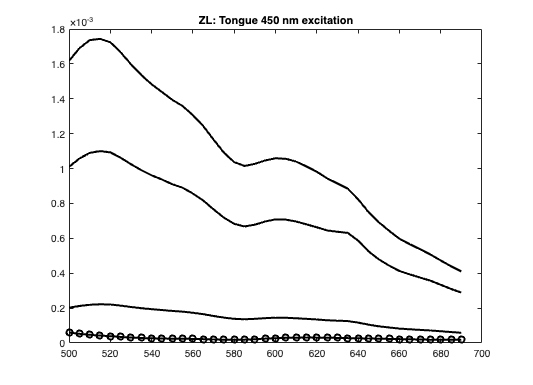

ieNewGraphWin; 
Z_tongue = ieReadSpectra('spd-2024-03-14-Z-450nm_tongue_90mA.mat',waves);   plot(waves,Z_tongue,'k','LineWidth',2); hold on;
Z_tongue = ieReadSpectra('spd-2024-03-14-Z-450nm_tongue_480mA.mat',waves);   plot(waves,Z_tongue,'k','LineWidth',2); hold on;
Z_tongue = ieReadSpectra('spd-2024-03-14-Z-450nm_tongue_870mA.mat',waves);   plot(waves,Z_tongue,'k','LineWidth',2); hold on;
plot(waves,predictedTongueReflectance_450nm_870mA ,'k-o','LineWidth',2);
title('ZL: Tongue 450 nm excitation');

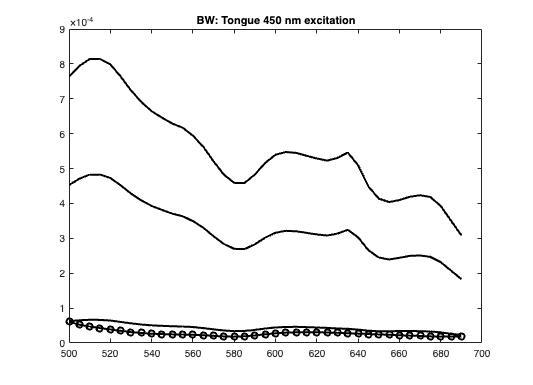

ieNewGraphWin; 
B_tongue = ieReadSpectra('spd-2024-03-19-B_450nm_tongue_90mA.mat',waves);   plot(waves,B_tongue,'k','LineWidth',2); hold on;
B_tongue = ieReadSpectra('spd-2024-03-19-B_450nm_tongue_480mA.mat',waves);   plot(waves,B_tongue,'k','LineWidth',2); hold on;
B_tongue = ieReadSpectra('spd-2024-03-19-B_450nm_tongue_870mA.mat',waves);   plot(waves,B_tongue,'k','LineWidth',2); hold on;
plot(waves,predictedTongueReflectance_450nm_870mA ,'k-o','LineWidth',2);
title('BW: Tongue 450 nm excitation');

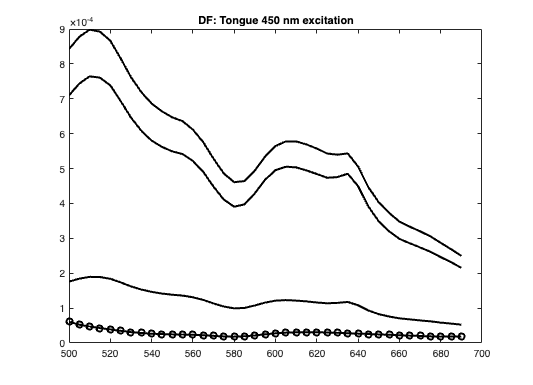

ieNewGraphWin; 
D_tongue = ieReadSpectra('spd-2024-03-19-D_450nm_tongue_90mA.mat',waves);   plot(waves,D_tongue,'k','LineWidth',2); hold on;
D_tongue = ieReadSpectra('spd-2024-03-19-D_450nm_tongue_480mA.mat',waves);   plot(waves,D_tongue,'k','LineWidth',2); hold on;
D_tongue = ieReadSpectra('spd-2024-03-19-D_450nm_tongue_870mA.mat',waves);   plot(waves,D_tongue,'k','LineWidth',2); hold on;
plot(waves,predictedTongueReflectance_450nm_870mA ,'k-o','LineWidth',2);
title('DF: Tongue 450 nm excitation');

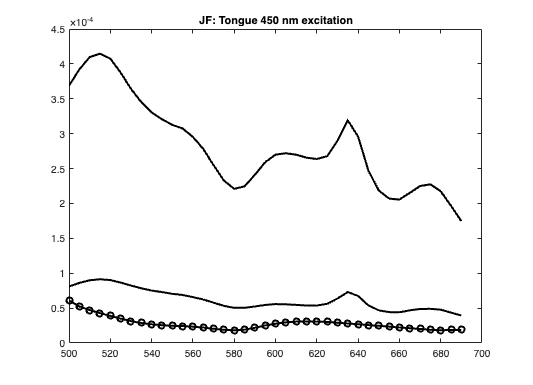

ieNewGraphWin; 
J_tongue = ieReadSpectra('spd-2024-03-12-450nm-J-tongue-90mA.mat',waves);   plot(waves,J_tongue,'k','LineWidth',2); hold on;
J_tongue = ieReadSpectra('spd-2024-03-12-450nm-J-tongue-460mA-1.mat',waves);   plot(waves,J_tongue,'k','LineWidth',2); hold on;
plot(waves,predictedTongueReflectance_450nm_870mA ,'k-o','LineWidth',2);
title('JF: Tongue 450 nm excitation');

### Now plotting for the lip

Note that these data are similar to the data collected on 3-07 and 3-08

### Measured lip radiance  for 400 nm light

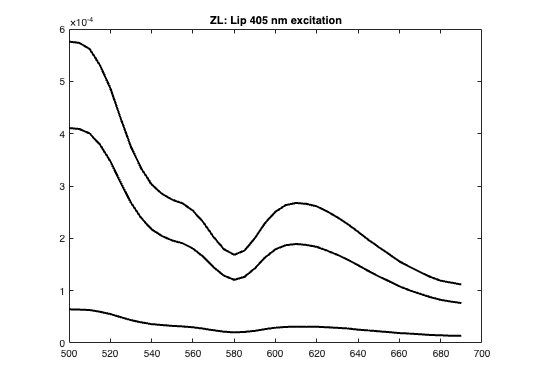

ieNewGraphWin; 
Z_lip = ieReadSpectra('spd-2024-03-14-Z-405nm_lip_90mA.mat',waves);       plot(waves,Z_lip,'k','LineWidth',2); hold on;
Z_lip = ieReadSpectra('spd-2024-03-14-Z-405nm_lip_560mA.mat',waves);      plot(waves,Z_lip,'k','LineWidth',2); hold on;
Z_lip = ieReadSpectra('spd-2024-03-14-Z-405nm_lip_980mA.mat',waves);    plot(waves,Z_lip,'k','LineWidth',2); hold on;
title('ZL: Lip 405 nm excitation');

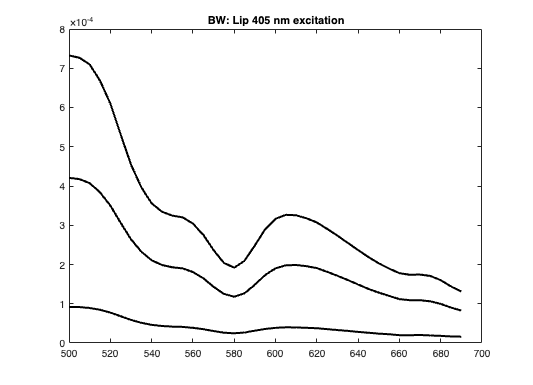

ieNewGraphWin; 
B_lip = ieReadSpectra('spd-2024-03-19-B_405nm_lip_90mA.mat',waves);       plot(waves,B_lip,'k','LineWidth',2); hold on;
B_lip = ieReadSpectra('spd-2024-03-19-B_405nm_lip_560mA.mat',waves);      plot(waves,B_lip,'k','LineWidth',2); hold on;
B_lip = ieReadSpectra('spd-2024-03-19-B_405nm_lip_980mA.mat',waves);    plot(waves,B_lip,'k','LineWidth',2); hold on;
title('BW: Lip 405 nm excitation');

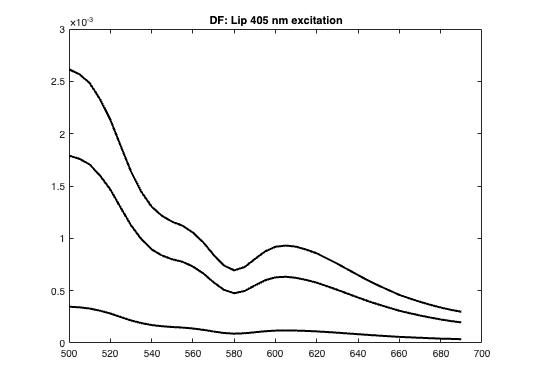

ieNewGraphWin; 
D_lip = ieReadSpectra('spd-2024-03-19-D_405nm_lip_90mA.mat',waves);       plot(waves,D_lip,'k','LineWidth',2); hold on;
D_lip = ieReadSpectra('spd-2024-03-19-D_405nm_lip_560mA.mat',waves);      plot(waves,D_lip,'k','LineWidth',2); hold on;
D_lip = ieReadSpectra('spd-2024-03-19-D_405nm_lip_980mA.mat',waves);    plot(waves,D_lip,'k','LineWidth',2); hold on;
title('DF: Lip 405 nm excitation');

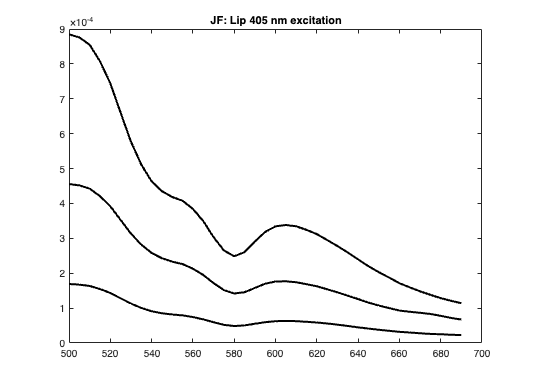

ieNewGraphWin; 
J_lip = ieReadSpectra('spd-2024-03-12-11-405nm-J-lip-90mA.mat',waves);       plot(waves,J_lip,'k','LineWidth',2); hold on;
J_lip = ieReadSpectra('spd-2024-03-12-11-405nm-J-lip-560mA.mat',waves);      plot(waves,J_lip,'k','LineWidth',2); hold on;
J_lip = ieReadSpectra('spd-2024-03-12-11-405nm-J-lip-980mA.mat',waves);    plot(waves,J_lip,'k','LineWidth',2); hold on;
title('JF: Lip 405 nm excitation');

### Measured lip radiance  for 415 nm light

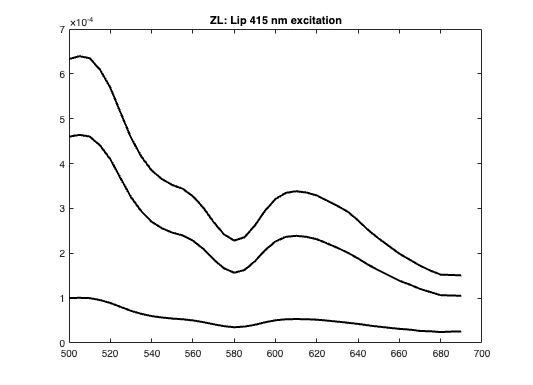

ieNewGraphWin; 
Z_lip = ieReadSpectra('spd-2024-03-14-Z-415nm_lip_80mA.mat',waves);       plot(waves,Z_lip,'k','LineWidth',2); hold on;
Z_lip = ieReadSpectra('spd-2024-03-14-Z-415nm_lip_460mA.mat',waves);      plot(waves,Z_lip,'k','LineWidth',2); hold on;
Z_lip = ieReadSpectra('spd-2024-03-14-Z-415nm_lip_910mA.mat',waves);    plot(waves,Z_lip,'k','LineWidth',2); hold on;
title('ZL: Lip 415 nm excitation');

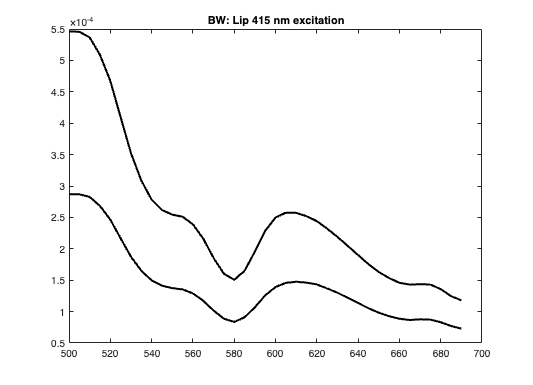

ieNewGraphWin; 
B_lip = ieReadSpectra('spd-2024-03-19-B_415nm_lip_460mA.mat',waves);       plot(waves,B_lip,'k','LineWidth',2); hold on;
B_lip = ieReadSpectra('spd-2024-03-19-B_415nm_lip_910mA.mat',waves);      plot(waves,B_lip,'k','LineWidth',2); hold on;
title('BW: Lip 415 nm excitation');

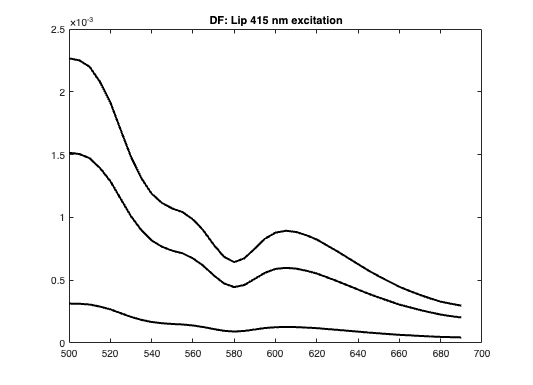

ieNewGraphWin; 
D_lip = ieReadSpectra('spd-2024-03-19-D_415nm_lip_90mA.mat',waves);       plot(waves,D_lip,'k','LineWidth',2); hold on;
D_lip = ieReadSpectra('spd-2024-03-19-D_415nm_lip_460mA.mat',waves);      plot(waves,D_lip,'k','LineWidth',2); hold on;
D_lip = ieReadSpectra('spd-2024-03-19-D_415nm_lip_910mA.mat',waves);    plot(waves,D_lip,'k','LineWidth',2); hold on;
title('DF: Lip 415 nm excitation');

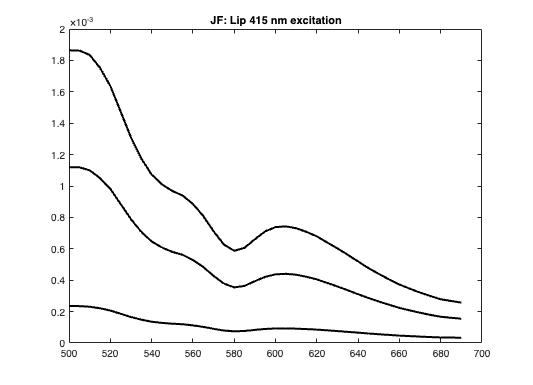

ieNewGraphWin; 
J_lip = ieReadSpectra('spd-2024-03-12-11-415nm-J-lip-80mA.mat',waves);       plot(waves,J_lip,'k','LineWidth',2); hold on;
J_lip = ieReadSpectra('spd-2024-03-12-11-415nm-J-lip-460mA.mat',waves);      plot(waves,J_lip,'k','LineWidth',2); hold on;
J_lip = ieReadSpectra('spd-2024-03-12-11-415nm-J-lip-910mA.mat',waves);    plot(waves,J_lip,'k','LineWidth',2); hold on;
title('JF: Lip 415 nm excitation');

### Measured lip radiance  for 450 nm light

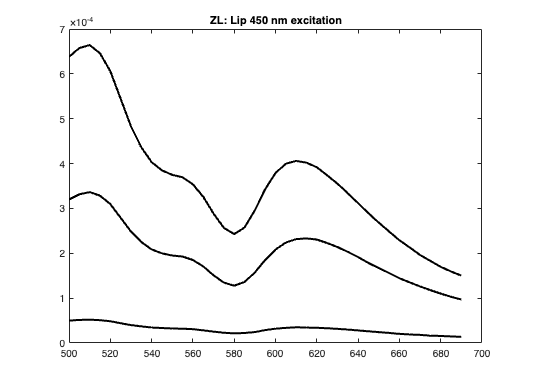

ieNewGraphWin; 
Z_lip = ieReadSpectra('spd-2024-03-14-Z-450nm_lip_90mA.mat',waves);       plot(waves,Z_lip,'k','LineWidth',2); hold on;
Z_lip = ieReadSpectra('spd-2024-03-14-Z-450nm_lip_480mA.mat',waves);      plot(waves,Z_lip,'k','LineWidth',2); hold on;
Z_lip = ieReadSpectra('spd-2024-03-14-Z-450nm_lip_870mA.mat',waves);    plot(waves,Z_lip,'k','LineWidth',2); hold on;
title('ZL: Lip 450 nm excitation');

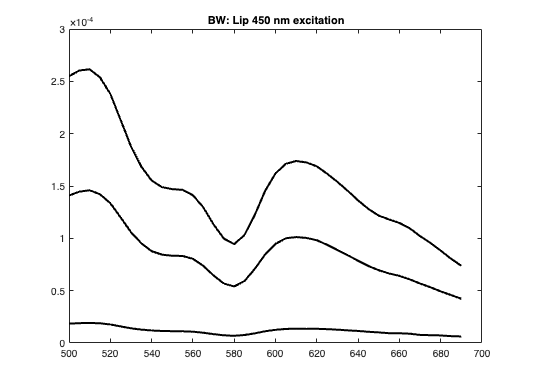

ieNewGraphWin; 
B_lip = ieReadSpectra('spd-2024-03-19-B_450nm_lip_90mA.mat',waves);       plot(waves,B_lip,'k','LineWidth',2); hold on;
B_lip = ieReadSpectra('spd-2024-03-19-B_450nm_lip_480mA.mat',waves);      plot(waves,B_lip,'k','LineWidth',2); hold on;
B_lip = ieReadSpectra('spd-2024-03-19-B_450nm_lip_870mA.mat',waves);    plot(waves,B_lip,'k','LineWidth',2); hold on;
title('BW: Lip 450 nm excitation');

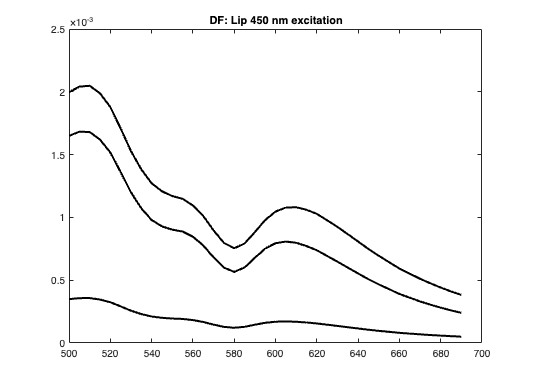

ieNewGraphWin; 
D_lip = ieReadSpectra('spd-2024-03-19-D_450nm_lip_90mA.mat',waves);       plot(waves,D_lip,'k','LineWidth',2); hold on;
D_lip = ieReadSpectra('spd-2024-03-19-D_450nm_lip_480mA.mat',waves);      plot(waves,D_lip,'k','LineWidth',2); hold on;
D_lip = ieReadSpectra('spd-2024-03-19-D_450nm_lip_870mA.mat',waves);    plot(waves,D_lip,'k','LineWidth',2); hold on;
title('DF: Lip 450 nm excitation');

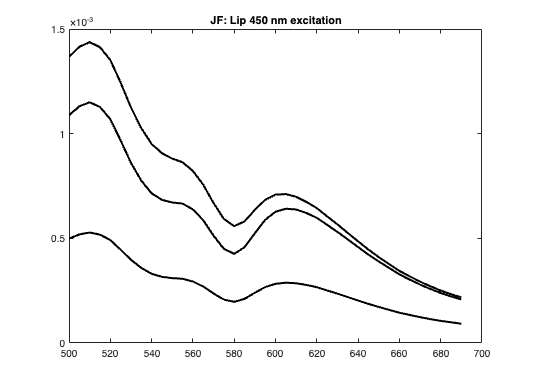

ieNewGraphWin; 
J_lip = ieReadSpectra('spd-2024-03-12-11-450nm-J-lip-90mA.mat',waves);       plot(waves,J_lip,'k','LineWidth',2); hold on;
J_lip = ieReadSpectra('spd-2024-03-12-11-450nm-J-lip-480nm.mat',waves);      plot(waves,J_lip,'k','LineWidth',2); hold on;
J_lip = ieReadSpectra('spd-2024-03-12-11-450nm-J-lip-870mA.mat',waves);    plot(waves,J_lip,'k','LineWidth',2); hold on;
title('JF: Lip 450 nm excitation');